# This script contains the development of the point 3.2) Estimation of the friction parameters.

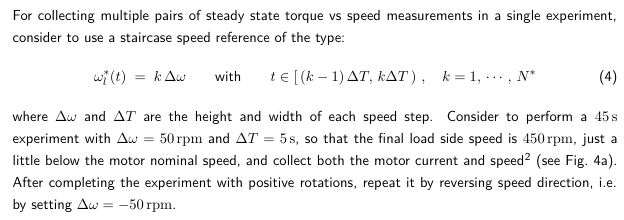

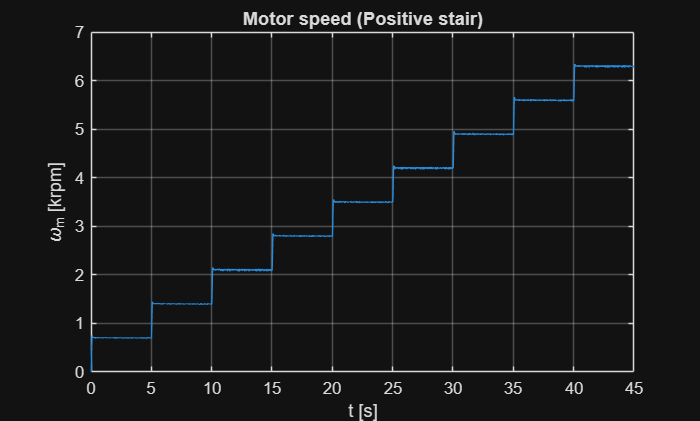




curr_positive = load('Lab_0\Generated_files\current_positive.mat');

volt_positive = load('Lab_0\Generated_files\voltage_positive.mat');

t = curr_positive.time;
ia = curr_positive.current_positive;
omega_l_positive  = volt_positive.voltage;

% Load Saved data (negative stair)

curr_negative = load('Lab_0\Generated_files\current_negative.mat');
volt_negative = load('Lab_0\Generated_files\voltage_negative.mat');


% Extract values and assing variales:
% tn = time;
% ian = negative stair current
% omega_ln = angle position for negative stair  

tn = volt_negative.time1;
ian = curr_negative.current_negative;
omega_l_negative = volt_negative.voltage;

% plot motor speed (positive stair)
figure
plot(t,omega_l_positive*gbox.N/1000);
title('Motor speed (Positive stair)')
grid on
xlabel('t [s]');
ylabel('\omega_m [krpm]');


% Apply of the low pass filter to find the motor current (initial
% current is very noisy)

sysHi = tf(rdp.wci^2, [1, 2*rdp.di*rdp.wci, rdp.wci^2]);
sysHi = c2d(sysHi, Ts, 'tustin');
[numHi, denHi] = tfdata(sysHi, 'v');


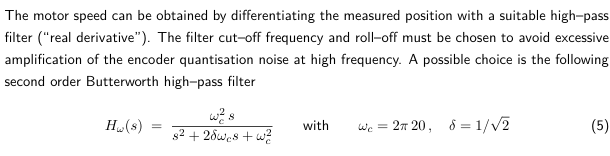

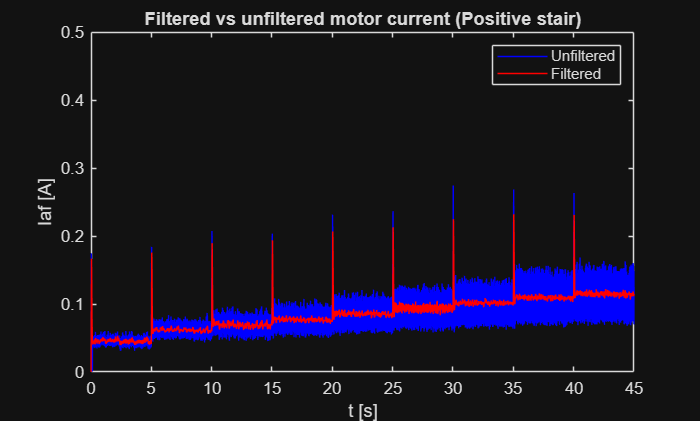

% Filter current (negative (iafn) and positive (iaf)

iaf = filter(numHi, denHi, ia);
iafn = filter(numHi, denHi, ian);


% Plot current (Positive stair) unfiletered and filtered values
figure
plot(t,ia,'b');
hold on
plot(t,iaf,'r');
title('Filtered vs unfiltered motor current (Positive stair)')
legend('Unfiltered','Filtered');

xlabel('t [s]');
ylabel('Iaf [A]');
axis([0 45 0 0.5])

## Compute mean velocities and current for each positive stair interval


% Compute means speed for each positive staircase interval (9 points, one for every 50 rpm increment, Totale time = 45 s) 

% create an empy vector omegal_med for mean speed
omegal_med = zeros(1,9);

% Impose an offset to cut the noisy values
offset = 500;

% Note: omega_l = 45001 values. T = 45000/45 = 1000 values every second. Every step has a duration of 5 s. 
% So 5000 data for every step. First interval is between 0 and 5000. 
% I apply offset so i start from 500 to 4500. After I performe
% the mean of the data between 500 and 4500. Secondo interval between 5500
% and 9500.

% Motor speed mean for positive stair
% Create 9 chunks of data 
% 
duration = 45; %s
T = round(size(omega_l_positive,1)/duration);
for x=1:1:9
   y1 = ((x-1)*5)*T+offset;
   y2 = 5*T*x - offset;
   omegal_med(x) = mean(omega_l_positive(y1:y2));
end

% Adjust unit measures and multiply N times (i need omega_mk)

omegal_med1 = omegal_med *rpm2rads*gbox.N;

% Same for the positive stair current

ia_med = zeros(1,9);

for x=1:1:9
   y1 = ((x-1)*5)*T+offset;
   y2 = 5*T*x - offset;
   ia_med(x) = mean(iaf(y1:y2));
end

% Derive Tau from motor current 

tau_med = mot.Kt*ia_med;


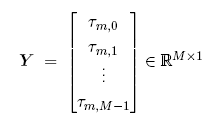


% Apply maximum likehood - Positive stair input (use ls = Sigma \ Y)

Y = tau_med';


% Build sigma transpose

Sigma = [(omegal_med1)' (sign(omegal_med1)/gbox.N)'];


% Compute LS. Note: We use left matrix division operator  "\" 
% as suggested at the end of point 4.1 in Lab0 Theoretical background

ls = Sigma \ Y;

% Return Beq and Tausf for positive stair input

Beq_lsp = ls(1,1);
Tausf_lsp = ls(2,1);


## Compute mean velocities and current for each negative stair interval

% Use the same procedure applied for positive stair input 

omegal_medn = zeros(1,9);

for x=1:1:9
   y1 = ((x-1)*5)*T+offset;
   y2 = 5*T*x - offset;
   omegal_medn(x) = mean(omega_l_negative(y1:y2));
end

omegal_medn1 = omegal_medn *gbox.N* rpm2rads;

% Compute current mean for each negative stair interval

ia_medn = zeros(1,9);

for x=1:1:9
   y1 = ((x-1)*5)*T+offset;
   y2 = 5*T*x - offset;
   ia_medn(x) = mean(iafn(y1:y2));
end


% Derive Tau from motor current 

tau_medn = mot.Kt*ia_medn;


Yn = tau_medn';


% Apply maximum likehood - Negative  stair input (use ls = Sigma \ Y)




Sigman = [(omegal_medn1)' (sign(omegal_medn1)/gbox.N)'];



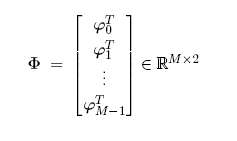



lsn = Sigman \ Yn;

Beq_lsn = lsn(1,1);

Tausf_lsn = lsn(2,1);


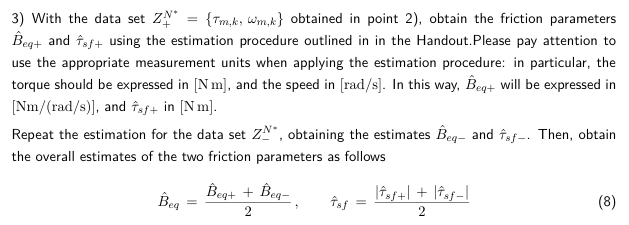


% Mean of positive e negative Beq and Tsf

Beq= (Beq_lsp + Beq_lsn)/2;
fprintf("Beq = %d Nm/(rad/s))",Beq);

Beq = 8.540115e-07 Nm/(rad/s))

Tausf= (abs(Tausf_lsp) + abs(Tausf_lsn))/2;
fprintf("Tausf = %d Nm", Tausf);

Tausf = 4.748915e-03 Nm

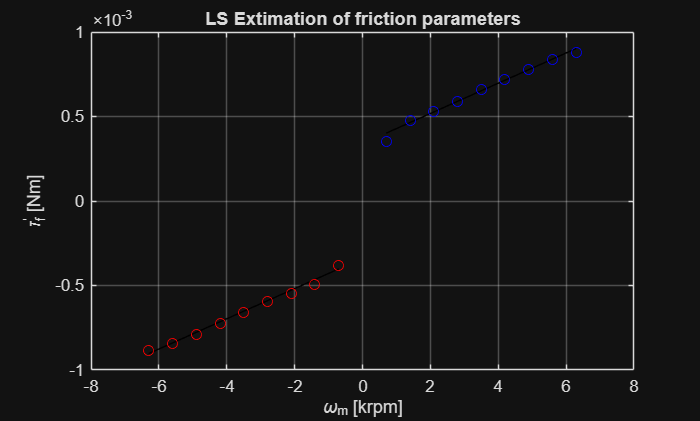

save('Lab_0\Generated_files\friction_value.mat','Beq','Tausf')

% Plot the LS estimation of frictional parameters

omegap = (50:50:450)*rpm2rads*gbox.N;
omegan = (-450:50:-50)*rpm2rads*gbox.N;

tau_primop = Beq*omegap+Tausf*sign(omegap)/gbox.N;
tau_primon = Beq*omegan+Tausf*sign(omegan)/gbox.N;
figure
plot(omegan/rpm2rads/1000,tau_primon,'k-');
hold on
plot(omegap/rpm2rads/1000,tau_primop,'k-');

plot(omegal_med1/rpm2rads/1000,tau_med,'bo');

plot(omegal_medn1/rpm2rads/1000,tau_medn,'ro');
grid on
xlabel('\omega_m [krpm]');
ylabel('\tau^''_f [Nm]');
title('LS Extimation of friction parameters')


% Compute the intervals 

V_tetha_p = (Y-Sigma*ls)'*(Y-Sigma*ls);
V_tetha_n = (Yn-Sigman*lsn)'*(Yn-Sigma*lsn);

lamda2_p = 1/(9-2)*V_tetha_p;
lamda2_n = 1/(9-2)*V_tetha_n;

cov_ls_p =  lamda2_p*inv(Sigma'*Sigma);
cov_ls_n =  lamda2_n*inv(Sigman'*Sigman);

var_Beq = (cov_ls_p(1,1) + cov_ls_n(1,1))/4;
var_tausf = (cov_ls_p(2,2) + cov_ls_n(2,2))/4;
sd_Beq = var.c * sqrt(var_Beq);
sd_tausf = var.c * sqrt(var_tausf);

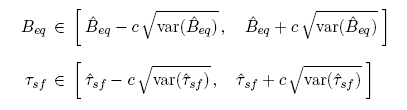

% Print the intervals values for Beq and tausf
fprintf("Confidence interval for Beq: [%d,%d] \n",Beq-sd_Beq,Beq+sd_Beq);

Confidence interval for Beq: [8.097636e-07,8.982593e-07] 


fprintf("Confidence interval for tausf: [%d,%d] \n",Tausf-sd_tausf,Tausf+sd_tausf);

Confidence interval for tausf: [4.493499e-03,5.004331e-03] 
